# **例题：预测众筹是否成功**

## 解决分类问题中样本不平衡问题：RUSBoost算法

clc;clear

先把当前文件夹修改成数据所在的这个文件夹。

cd 'C:\Users\sxjmqf\Desktop\机器学习进阶课程\2.预测众筹是否成功的数据集'

**导入附件1的数据**

%% 导入数据
[~, ~, raw] = xlsread('调整后的附件1.xlsx','Sheet1','A2:J668');
stringVectors = string(raw(:,[3,8,10]));
stringVectors(ismissing(stringVectors)) = '';
raw = raw(:,[1,2,4,5,6,7,9]);

%% 创建输出变量
data = reshape([raw{:}],size(raw));

%% 创建表
data1 = table;

%% 将导入的数组分配给列变量名称
data1.VarName1 = data(:,1);
data1.VarName2 = data(:,2);
data1.VarName3 = categorical(stringVectors(:,1));
data1.VarName4 = data(:,3);
data1.VarName5 = data(:,4);
data1.VarName6 = data(:,5);
data1.VarName7 = data(:,6);
data1.VarName8 = categorical(stringVectors(:,2));
data1.VarName9 = data(:,7);
data1.VarName10 = categorical(stringVectors(:,3));

%% 清除临时变量
clearvars data raw stringVectors;

导入要预测的数据（附件2的数据）

%% 导入数据
[~, ~, raw] = xlsread('调整后的附件2.xlsx','Sheet1','A2:I22');
stringVectors = string(raw(:,[3,8]));
stringVectors(ismissing(stringVectors)) = '';
raw = raw(:,[1,2,4,5,6,7,9]);

%% 创建输出变量
data = reshape([raw{:}],size(raw));

%% 创建表
data2 = table;

%% 将导入的数组分配给列变量名称
data2.VarName1 = data(:,1);
data2.VarName2 = data(:,2);
data2.VarName3 = categorical(stringVectors(:,1));
data2.VarName4 = data(:,3);
data2.VarName5 = data(:,4);
data2.VarName6 = data(:,5);
data2.VarName7 = data(:,6);
data2.VarName8 = categorical(stringVectors(:,2));
data2.VarName9 = data(:,7);

%% 清除临时变量
clearvars data raw stringVectors;

**返回表中各个指标的信息**

summary(data1)  


Variables:

    VarName1: 667×1 double

        Values:

            Min            1000 
            Median        15000 
            Max       6.772e+06 

    VarName2: 667×1 double

        Values:

            Min        1        
            Median     6        
            Max       17        

    VarName3: 667×1 categorical

        Values:

            否    401       
            是    266       

    VarName4: 667×1 double

        Values:

            Min        1        
            Median     5        
            Max       27        

    VarName5: 667×1 double

        Values:

            Min          30     
            Median      720     
            Max       3e+05     

    VarName6: 667×1 double

        Values:

            Min          2      
            Median      10      
            Max       9800      

    VarName7: 667×1 double

        

tabulate(data1.VarName10)

  Value    Count   Percent
      否      584     87.56%
      是       83     12.44%


这是导出来的RUSBoost的代码

trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7', 'VarName8', 'VarName9'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName10;


% Train a classifier
% This code specifies all the classifier options and trains the classifier.
template = templateTree(...
    'MaxNumSplits', 20);
classificationEnsemble = fitcensemble(...
    predictors, ...
    response, ...
    'Method', 'RUSBoost', ...
    'NumLearningCycles', 100, ...
    'Learners', template, ...
    'LearnRate', 0.1, ...
    'ClassNames', categorical({'否'; '是'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
ensemblePredictFcn = @(x) predict(classificationEnsemble, x);
trainedClassifier.predictFcn = @(x) ensemblePredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7', 'VarName8', 'VarName9'};
trainedClassifier.ClassificationEnsemble = classificationEnsemble;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7', 'VarName8', 'VarName9'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName10;
isCategoricalPredictor = [false, false, true, false, false, false, false, true, false];

% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationEnsemble, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');

网格搜索：找到使AUC最大时对应的参数（你也可以使用之前学的F1分数）

小技巧：提升法中树的大小通常要小于装袋法的大小，因此最大分裂数MaxNumSplits在提升法中要设置的小一点。（RUSBoost是提升法的一种）

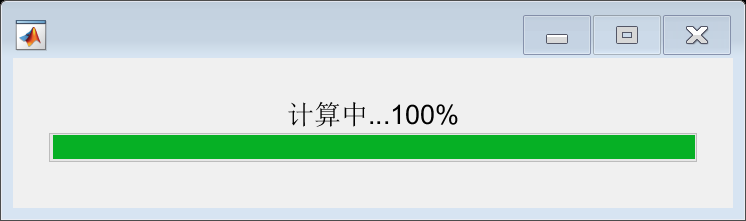

trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7', 'VarName8', 'VarName9'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName10;
isCategoricalPredictor = [false, false, true, false, false, false, false, true, false];

group = response;  % y所在的那一列（真实的类别）
ClassNames = unique(response); % y中各类的名称
% 假设我们更关心众筹成功了，就可以让正类为“是”
kk = 2;   % 指定正类，kk是正类在ClassNames中的位置
posclass = ClassNames(kk); % 正类的名称

MaxNumSplits = 10:10:100;  % 网格搜索设置的最大分裂数的范围
NumLearningCycles = 10:10:100;  % RUSBoost中决策树的个数范围
num_i = length(MaxNumSplits);
num_j = length(NumLearningCycles);
AUC = zeros(num_i,num_j);
mywaitbar = waitbar(0); 
TOTAL_NUM = num_i*num_j; 
now_num = 0;
for i = 1:num_i
    for j = 1:num_j
        rng(520)  % 设定随机数种子，保证结果的可重复性(这里的520也可以换成其他的数字)
        % Train a classifier
        % This code specifies all the classifier options and trains the classifier.
        template = templateTree(...
            'MaxNumSplits', MaxNumSplits(i));
        classificationEnsemble = fitcensemble(...
            predictors, ...
            response, ...
            'Method', 'RUSBoost', ...
            'NumLearningCycles',NumLearningCycles(j), ...
            'Learners', template, ...
            'LearnRate', 0.1, ...
            'ClassNames', categorical({'否'; '是'}));
        
        % Create the result struct with predict function
        predictorExtractionFcn = @(t) t(:, predictorNames);
        ensemblePredictFcn = @(x) predict(classificationEnsemble, x);
        trainedClassifier.predictFcn = @(x) ensemblePredictFcn(predictorExtractionFcn(x));
        
        % Add additional fields to the result struct
        trainedClassifier.RequiredVariables = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7', 'VarName8', 'VarName9'};
        trainedClassifier.ClassificationEnsemble = classificationEnsemble;
        trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
        trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
        
        % Extract predictors and response
        % This code processes the data into the right shape for training the
        % model.
        inputTable = trainingData;
        predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7', 'VarName8', 'VarName9'};
        predictors = inputTable(:, predictorNames);
        response = inputTable.VarName10;
        isCategoricalPredictor = [false, false, true, false, false, false, false, true, false];
        
        % Perform cross-validation
        partitionedModel = crossval(trainedClassifier.ClassificationEnsemble, 'KFold', 5);
        
        % Compute validation predictions
        [validationPredictions, validationScores] = kfoldPredict(partitionedModel);
        
        % 计算auc
        [~,~,~,auc] = perfcurve(group,validationScores(:,kk),posclass);  % 前三个输出都不需要
        AUC(i,j) = auc;
        
        % 更新进度条
        now_num = now_num+1;
        mystr=['计算中...',num2str(100*now_num/TOTAL_NUM),'%'];   
        waitbar(now_num/TOTAL_NUM,mywaitbar,mystr);
    end
end

% save AUC.mat AUC  % 把这个来之不易的结果保存到本地
load  AUC.mat 

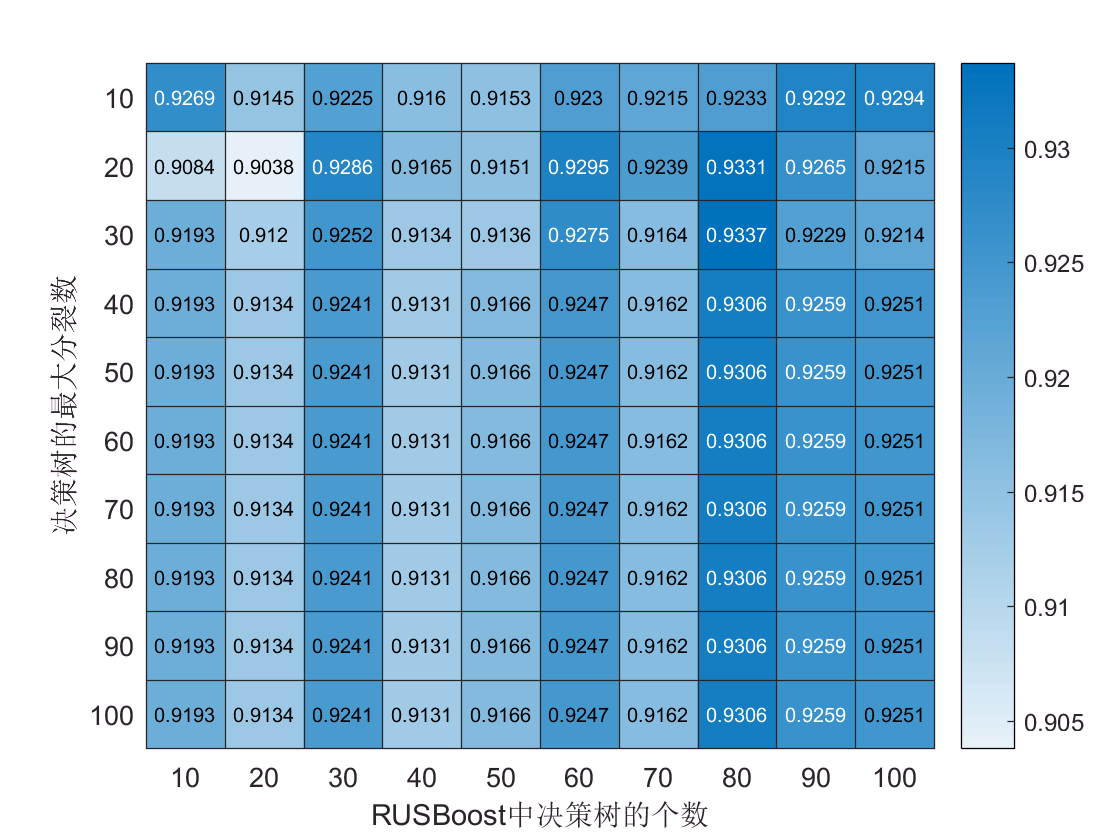

figure(1)
MaxNumSplits = 10:10:100;  % 网格搜索设置的最大分裂数的范围
NumLearningCycles = 10:10:100;  % RUSBoost中决策树的个数范围
h_graph = heatmap(NumLearningCycles,MaxNumSplits,AUC); 
h_graph.XLabel = 'RUSBoost中决策树的个数';
h_graph.YLabel = '决策树的最大分裂数';

best_AUC = max(AUC(:))

best_roc = 0.9337

[r,c] = find(AUC== best_AUC,1);
best_MaxNumSplits = MaxNumSplits(r)  % 决策树的最大分裂数

best_MaxNumSplits = 30

best_NumLearningCycles = NumLearningCycles(c) % RUSBoost中决策树的个数

best_NumLearningCycles = 80

用最优的模型进行预测

注意：如果模型中具有随机性，那么最后得到的结果可能会变化。

我们可以使用rng指定一个固定的随机数种子，这样我们每次运行的结果都会相同。

rng(520)  % 设定随机数种子，保证结果的可重复性(这里的520也可以换成其他的数字)
trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7', 'VarName8', 'VarName9'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName10;

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
template = templateTree(...
    'MaxNumSplits', best_MaxNumSplits);
classificationEnsemble = fitcensemble(...
    predictors, ...
    response, ...
    'Method', 'RUSBoost', ...
    'NumLearningCycles', best_NumLearningCycles, ...
    'Learners', template, ...
    'LearnRate', 0.1, ...
    'ClassNames', categorical({'否'; '是'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
ensemblePredictFcn = @(x) predict(classificationEnsemble, x);
trainedClassifier.predictFcn = @(x) ensemblePredictFcn(predictorExtractionFcn(x));

[class_hat, score] = trainedClassifier.predictFcn(data2)

class_hat = 21×1 categorical 数组
     是 
     否 
     是 
     否 
     否 
     是 
     是 
     否 
     否 
     否 
     是 
     否 
     否 
     否 
     否 
     是 
     否 
     否 
     否 
     否 
     否 


score =     1.9341    2.3357
    3.6817    0.5881
    1.4569    2.8129
    2.1522    2.1176
    3.9266    0.3433
    1.5598    2.7100
    0.2424    4.0274
    3.9022    0.3677
    2.8414    1.4284
    4.0412    0.2287


score = score./ sum(score,2)  % 调整预测的概率

score =     0.4530    0.5470
    0.8623    0.1377
    0.3412    0.6588
    0.5040    0.4960
    0.9196    0.0804
    0.3653    0.6347
    0.0568    0.9432
    0.9139    0.0861
    0.6655    0.3345
    0.9464    0.0536


**使用最大相关最小冗余算法（mRMR）得到指标的重要性**

**（注意，下面的代码在MATLAB 2019b以及之后的版本才可以运行）**

trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4', 'VarName5', 'VarName6', 'VarName7', 'VarName8', 'VarName9'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName10;

上面的代码就是分类工具箱自动导出的，我这里直接搬过来了

下面我们只用加上一行代码即可调用mRMR模型：

% [idx,importance] = fscmrmr(predictors,response)

idx表示指标重要性从高到低的指标的编号

importance是从第一个指标到最后一个指标的重要性，我们将其归一化

% % 可以将重要性归一化到[0 1]区间内
% % importance(importance<0) = 0;
% importance = importance./sum(importance)
% % 画一个柱状图
% figure(2)
% h_bar = bar(importance);
% % h_bar.Parent.XTickLabel =predictors.Properties.VariableNames;  % 设置每个柱子的标签
% % 也可以手工指定这里的指标名称
% tmp = "目标金额	众筹持续时长（周）	是否设置了1元抽奖活动	设置了几种支持的金额	最多支持的金额	最少支持的金额	商品发货时间(周)	有无视频	图片数量";
% h_bar.Parent.XTickLabel = strsplit(tmp,'	');
% h_bar.Parent.XTickLabelRotation = 45;  % 标签旋转45度
% h_bar.Parent.TickLabelInterpreter =  'none';  % 不使用latex语法